A1 = [0, 1; 0, 0];
B1 = [0; 1];
C1 = [1 , 0];
T = 0.2;
Bd = 0;
ic = 1;

Ad = expm(A1*T)

Ad =     1.0000    0.2000
         0    1.0000


for i = 1:10
    Bd = Bd + (A1^(i-1)*T^i)/factorial(i);
end
Bd = Bd*B1

Bd =     0.0200
    0.2000


syms K1 K2;
K = [K1 K2];
Fd = Ad - Bd*K

$$Fd = \left(\begin{array}{cc} 1-\frac{K_{1}}{50} & \frac{1}{5}-\frac{K_{2}}{50}\\ -\frac{K_{1}}{5} & 1-\frac{K_{2}}{5} \end{array}\right)$$

syms z;
I = eye(2);
D(z) = det([z*I - Fd])

$$D(z) = \frac{K_{1}}{50}-\frac{K_{2}}{5}-2\,z+\frac{K_{1}\,z}{50}+\frac{K_{2}\,z}{5}+z^{2}+1$$

Z_ = [0.8, 0.2; 
    1, -0.3;
    0.6, -0.3;
    0.7j, -0.7j;
    -0.3+0.8j, -0.3-0.8j;
    0.8+0.3j, 0.8-0.3j];

Z = sym([0 0 0 0 0 0]);

for i = 1:6
    Z(i) = sym(expand((z - Z_(i, 1))*(z - Z_(i, 2))));
end

Z(1)

$$ans = z^{2}-z+\frac{4}{25}$$

Z(2)

$$ans = z^{2}-\frac{7\,z}{10}-\frac{3}{10}$$

Z(3)

$$ans = z^{2}-\frac{3\,z}{10}-\frac{9}{50}$$

Z(4)

$$ans = z^{2}+\frac{49}{100}$$

Z(5)

$$ans = z^{2}+\frac{3\,z}{5}+\frac{73}{100}$$

Z(6)

$$ans = z^{2}-\frac{8\,z}{5}+\frac{73}{100}$$

[K_1,~,~] = computeK(Z_(1, :),Ad,Bd)

$$K\_1 = \left(\begin{array}{cc} -4 & -\frac{23}{5} \end{array}\right)$$

%[K_2,~,~] = computeK([1, -0.3],Ad,Bd)

solve (D(z) == Z(2), K1, K2)

ans = struct with fields:
    K1: (5*(13*z - 13))/(z + 1)
    K2: 0


K_2 = [0 -65]

K_2 =      0   -65



[K_3,~,~] = computeK(Z_(3, :),Ad,Bd)

$$K\_3 = \left(\begin{array}{cc} -13 & -\frac{36}{5} \end{array}\right)$$

[K_4,~,~] = computeK(Z_(4, :),Ad,Bd)

$$K\_4 = \left(\begin{array}{cc} -\frac{149}{4} & -\frac{251}{40} \end{array}\right)$$

[K_5,~,~] = computeK(Z_(5, :),Ad,Bd)

$$K\_5 = \left(\begin{array}{cc} -\frac{233}{4} & -\frac{287}{40} \end{array}\right)$$

[K_6,~,~] = computeK(Z_(6, :),Ad,Bd)

$$K\_6 = \left(\begin{array}{cc} -\frac{13}{4} & -\frac{67}{40} \end{array}\right)$$


K_true = [K_1; K_2; K_3; K_4; K_5; K_6];

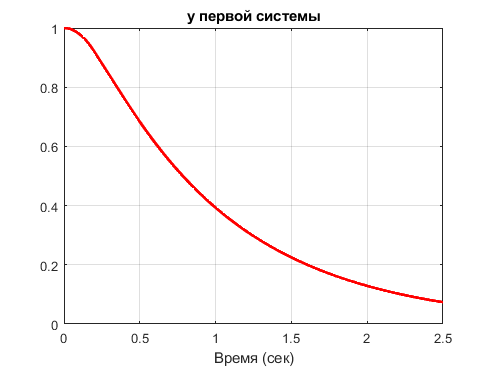

K1_ = K_1(1);
K2_ = K_1(2);

simtime = 2.5;
out = sim("laba2.slx", simtime);
plot(out.y, 'r', 'LineWidth',2)
grid on
title('y первой системы')

xlabel("Время (сек)")
ylabel("")

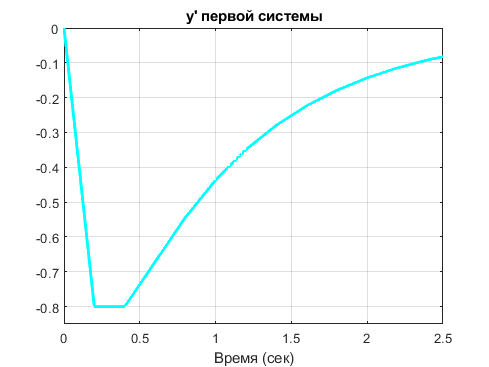

plot(out.y_dot, 'c', 'LineWidth',2)
grid on
title("y' первой системы")
xlabel("Время (сек)")
ylabel("")
ylim([-0.85 0])

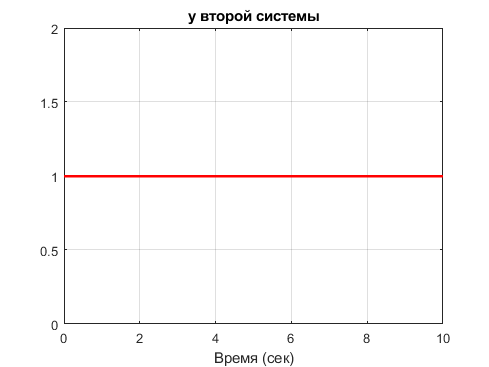

K1_ = K_2(1);
K2_ = K_2(2);

simtime = 10;
out = sim("laba2.slx", simtime);
plot(out.y,'r', 'LineWidth',2)
grid on
title('y второй системы')
xlabel("Время (сек)")
ylabel("")

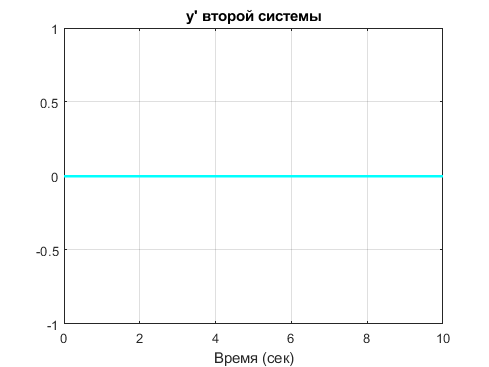

plot(out.y_dot, 'c', 'LineWidth',2)
grid on
title('y'' второй системы')
xlabel("Время (сек)")
ylabel("")

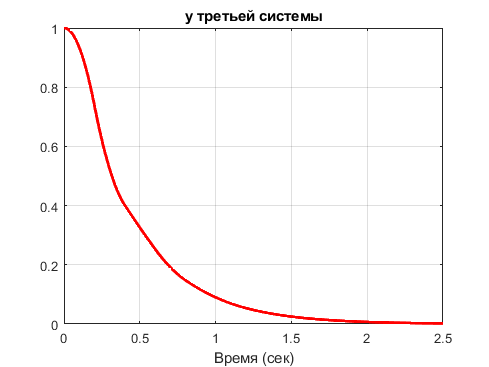

K1_ = K_3(1);
K2_ = K_3(2);

simtime = 2.5;
out = sim("laba2.slx", simtime);
plot(out.y,'r', 'LineWidth',2)
grid on
title('y третьей системы')
xlabel("Время (сек)")
ylabel("")

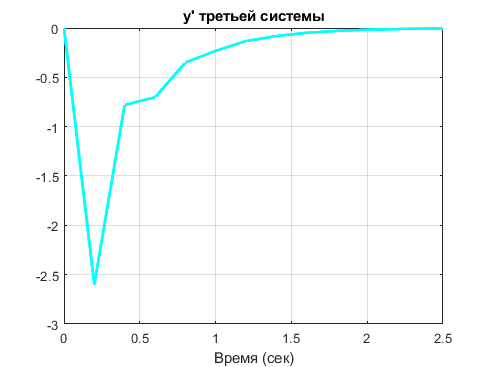

plot(out.y_dot, 'c', 'LineWidth',2)
grid on
title('y'' третьей системы')
xlabel("Время (сек)")
ylabel("")

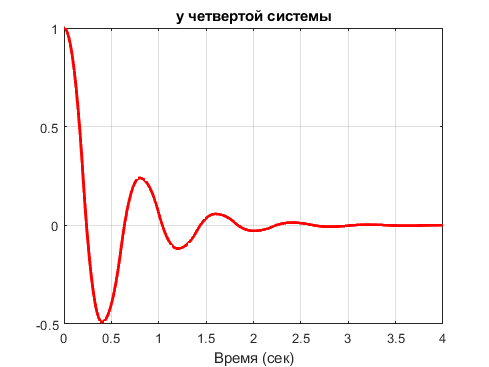

K1_ = K_4(1);
K2_ = K_4(2);

simtime = 4;
out = sim("laba2.slx", simtime);
plot(out.y,'r', 'LineWidth',2)
grid on
title('y четвертой системы')
xlabel("Время (сек)")
ylabel("")

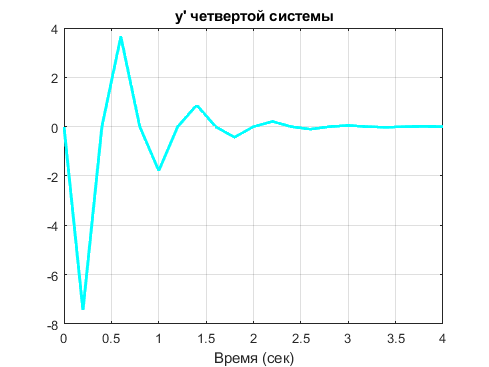

plot(out.y_dot, 'c', 'LineWidth',2)
grid on
title('y'' четвертой системы')
xlabel("Время (сек)")
ylabel("")

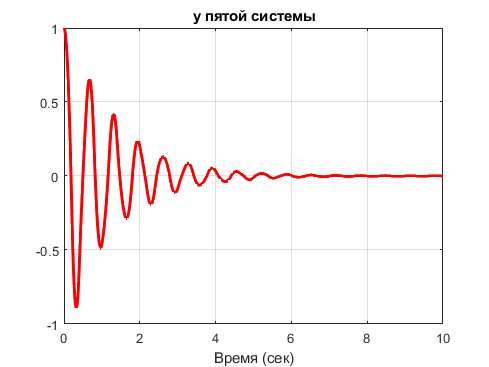

K1_ = K_5(1);
K2_ = K_5(2);

simtime = 10;
out = sim("laba2.slx", simtime);
plot(out.y,'r', 'LineWidth',2)
grid on
title('y пятой системы')
xlabel("Время (сек)")
ylabel("")

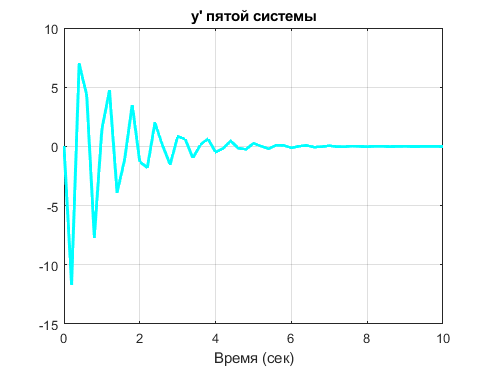

plot(out.y_dot, 'c', 'LineWidth',2)
grid on
title('y'' пятой системы')
xlabel("Время (сек)")
ylabel("")

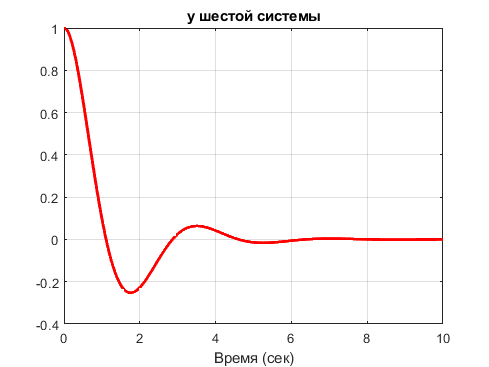

K1_ = K_6(1);
K2_ = K_6(2);

simtime = 10;
out = sim("laba2.slx", simtime);
plot(out.y,'r', 'LineWidth',2)
grid on
title('y шестой системы')
xlabel("Время (сек)")
ylabel("")

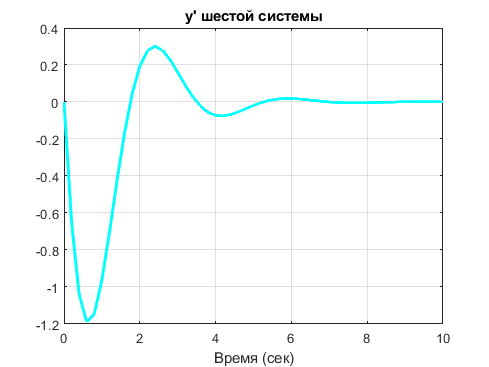

plot(out.y_dot,'c', 'LineWidth',2)
grid on
title('y'' шестой системы')
xlabel("Время (сек)")
ylabel("")

ббббб

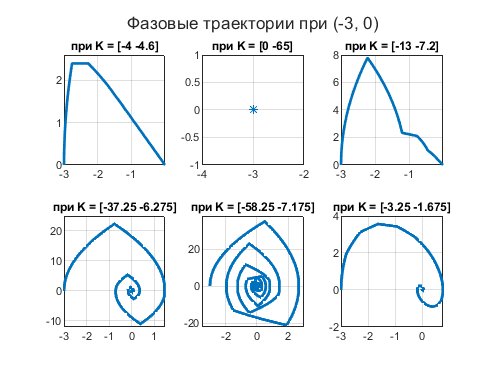

ic = -3;

K1_ = K_1(1);
K2_ = K_1(2);
phasemanyplots(ic)
phaseplots(K1_, K2_, 10)
ylim([0 2.6])


K1_ = K_2(1);
K2_ = K_2(2);
nexttile
phaseplots(K1_, K2_, 0.1)
K1_ = K_3(1);
K2_ = K_3(2);
nexttile
phaseplots(K1_, K2_, 10)
K1_ = K_4(1);
K2_ = K_4(2);
nexttile
phaseplots(K1_, K2_, 10)
ylim([-12 25])

K1_ = K_5(1);
K2_ = K_5(2);
nexttile
phaseplots(K1_, K2_, 10)
ylim([-22 38])
xlim([-3.5 3])

K1_ = K_6(1);
K2_ = K_6(2);
nexttile
phaseplots(K1_, K2_, 10)

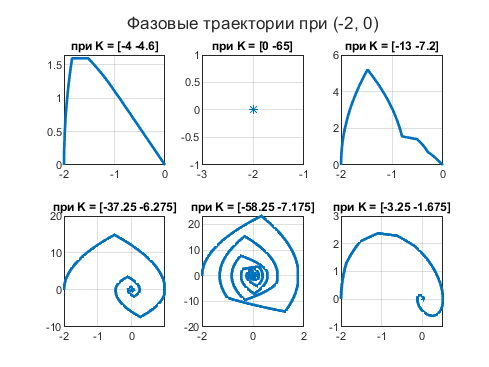

ic = -2;

K1_ = K_1(1);
K2_ = K_1(2);
phasemanyplots(ic)
phaseplots(K1_, K2_, 10)
ylim([0 1.65])

K1_ = K_2(1);
K2_ = K_2(2);
nexttile
phaseplots(K1_, K2_, 0.1)
K1_ = K_3(1);
K2_ = K_3(2);
nexttile
phaseplots(K1_, K2_, 10)
K1_ = K_4(1);
K2_ = K_4(2);
nexttile
phaseplots(K1_, K2_, 10)
K1_ = K_5(1);
K2_ = K_5(2);
nexttile
phaseplots(K1_, K2_, 10)
K1_ = K_6(1);
K2_ = K_6(2);
nexttile
phaseplots(K1_, K2_, 10)

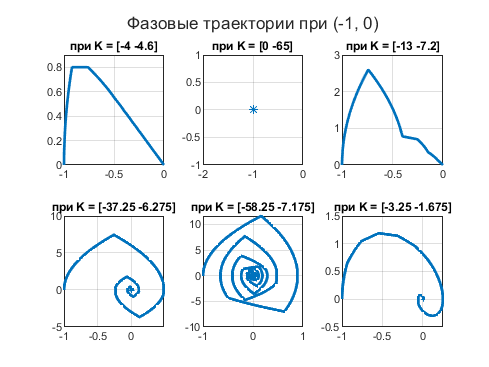

ic = -1;

K1_ = K_1(1);
K2_ = K_1(2);
phasemanyplots(ic)
phaseplots(K1_, K2_, 10)
ylim([0 0.9])

K1_ = K_2(1);
K2_ = K_2(2);
nexttile
phaseplots(K1_, K2_, 0.1)
K1_ = K_3(1);
K2_ = K_3(2);
nexttile
phaseplots(K1_, K2_, 10)
K1_ = K_4(1);
K2_ = K_4(2);
nexttile
phaseplots(K1_, K2_, 10)
K1_ = K_5(1);
K2_ = K_5(2);
nexttile
phaseplots(K1_, K2_, 10)
K1_ = K_6(1);
K2_ = K_6(2);
nexttile
phaseplots(K1_, K2_, 10)

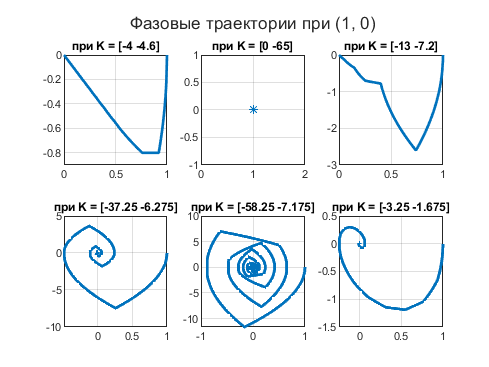

ic = 1;

K1_ = K_1(1);
K2_ = K_1(2);
phasemanyplots(ic)
phaseplots(K1_, K2_, 10)
ylim([-0.9 0])

K1_ = K_2(1);
K2_ = K_2(2);
nexttile
phaseplots(K1_, K2_, 0.1)
K1_ = K_3(1);
K2_ = K_3(2);
nexttile
phaseplots(K1_, K2_, 10)
K1_ = K_4(1);
K2_ = K_4(2);
nexttile
phaseplots(K1_, K2_, 10)
K1_ = K_5(1);
K2_ = K_5(2);
nexttile
phaseplots(K1_, K2_, 10)
K1_ = K_6(1);
K2_ = K_6(2);
nexttile
phaseplots(K1_, K2_, 10)

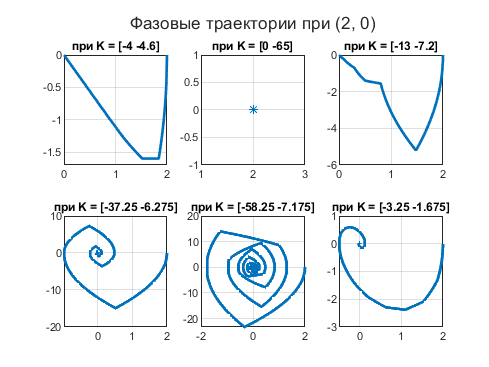

ic = 2;

K1_ = K_1(1);
K2_ = K_1(2);
phasemanyplots(ic)
phaseplots(K1_, K2_, 10)
ylim([-1.7 0])

K1_ = K_2(1);
K2_ = K_2(2);
nexttile
phaseplots(K1_, K2_, 0.1)
K1_ = K_3(1);
K2_ = K_3(2);
nexttile
phaseplots(K1_, K2_, 10)
K1_ = K_4(1);
K2_ = K_4(2);
nexttile
phaseplots(K1_, K2_, 10)
K1_ = K_5(1);
K2_ = K_5(2);
nexttile
phaseplots(K1_, K2_, 10)
K1_ = K_6(1);
K2_ = K_6(2);
nexttile
phaseplots(K1_, K2_, 10)

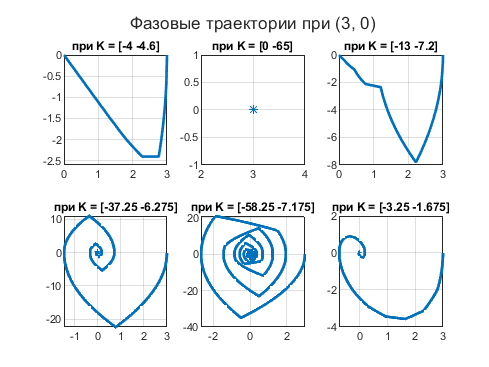

ic = 3;

K1_ = K_1(1);
K2_ = K_1(2);
phasemanyplots(ic)
phaseplots(K1_, K2_, 10)
ylim([-2.6 0])

K1_ = K_2(1);
K2_ = K_2(2);
nexttile
phaseplots(K1_, K2_, 0.1)
K1_ = K_3(1);
K2_ = K_3(2);
nexttile
phaseplots(K1_, K2_, 10)
K1_ = K_4(1);
K2_ = K_4(2);
nexttile
phaseplots(K1_, K2_, 10)
K1_ = K_5(1);
K2_ = K_5(2);
nexttile
phaseplots(K1_, K2_, 10)
K1_ = K_6(1);
K2_ = K_6(2);
nexttile
phaseplots(K1_, K2_, 10)

function [K,param,conditions] = computeK(vec,A,B) 
    [C,~,ic] = unique(vec);
    a_counts = accumarray(ic,1);
    value_counts = [C', a_counts];
    G = [];
    for i = 1:size(C')
        G = blkdiag(G,diag(repelem(value_counts(i,1),value_counts(i,2)))+diag(repelem(1,value_counts(i,2)-1),1));
    end
    Y = ones(size(B'));
    P = sym('P', size(A));
    sys = A*P-P*G==B*Y;
    Sol = solve(sys, P,'ReturnConditions',true);
    trSol = [];
    fields = fieldnames(Sol);
    for i = 1:(length(fields)-2)
        trSol = [trSol,getfield(Sol,string(fields(i)))];
    end
    trSol = reshape(trSol,size(P));
    K = -Y/trSol;
    param = getfield(Sol,"parameters");
    conditions = getfield(Sol,"conditions");
end

function phaseplots(K1_, K2_, t)
    K1_ = double(K1_);
    K2_ = double(K2_);    
    out = sim("laba2.slx", t);
    if K1_ == 0
        plot(out.y.Data, out.y_dot.Data, '*');
    else 
        plot(out.y.Data, out.y_dot.Data, 'LineWidth',2)
    end
    grid on;
    title(['при K = [' num2str(K1_) ' ' num2str(K2_) ']'])
end

function phasemanyplots(ic1)
    figure
    t = tiledlayout(2,3);
    title(t, ['Фазовые траектории при (' num2str(ic1) ', 0)'])
    nexttile
end